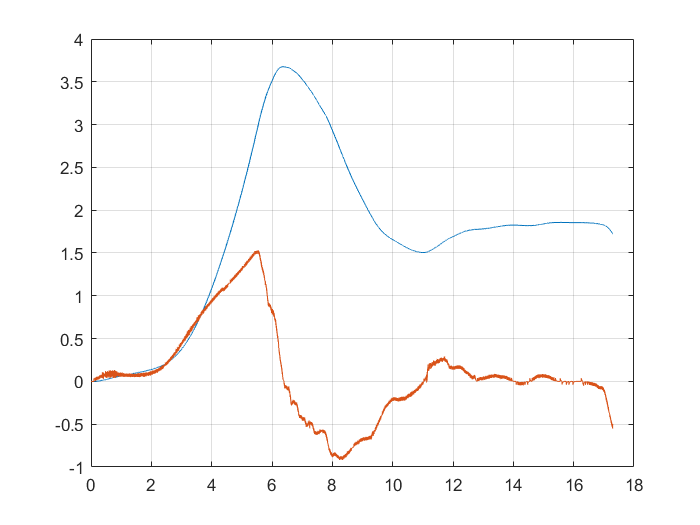


%-------SETTINGS-------------
filesToUse = [2,4,5];   % Use all files if empty
combinde = true;    % Combinde all active files to one plot
newFileName = '';   % Name if you combinde plots
rows=[2];         % rows you want to plot (1 is time)


%-------SCRIPT---------------
files=getFiles();

if isempty(filesToUse)
    filesToUse=1:length(files) %Use all files
end

if (combinde==true)
    hold on
    for i=filesToUse
        handle=autoPloter(files(i),rows);
    end
    hold off
    
    grid on
    %add xlim and stuff here if needed
    
    %---------------------------------
    if isempty(newFileName)
        newFileName=files(i).name;
    end
    saveas(handle,newFileName) %Save as fig
    exportgraphics(handle,newFileName+".pdf",'ContentType','vector')
else
    for i=1:filesToUse
        handle=autoPloter(files(i),rows);   
        grid on
        %add xlim and stuff here if needed
        
        %-----------------------------------
        name = files(i).name;
        name=name(1:length(name)-4);  
        saveas(handle,name) %Save as fig
        exportgraphics(handle,name+".pdf",'ContentType','vector')
    end
end